# Surface Dielectric Barrier Discharge Analysis Code

    The purpose of this code is to interpert the electrical characterisitcs of surface dielectric barrier discharge and return plasma parameters such as electron density, reduced electric field, discharge current, dielectric capacitance, and gap voltage. This is done by modeling the plasma parameters using the circuit shown in Figure 1. This circuit is modified from the tradtiional volume DBD simpilist circuit first used by Manly in the 1850s. The following code will go over the analysis in steps as they are done in the code itself. This is done to help others modify and add to the code as more knowledge is aquired in interpreting the electrical charactersitics of SDBD's.

## Function Dependencies

Needed Matlab Pakages

OscopeReadin -- A function designed specifaclly for reading in the CSV readout given by Tektronix Oscilliscopes, specifically the model MDO31604, but it should work with all tektronix osilliscope when saved as a csv file. 

## Expected Inputs 

PathOff -- Path pointing to a directoy containing Tektronix csv files at low voltages. Assumes a sin wave excitation volta

In order for the code to function the required inputs are in the form of raw csv files given by a tektronix oscilliscope. As the OscopeReadin Function gets added to the flexibilty of data input will hopefully increase. 

In order to fully characterize the DBD's data needs to be taken both with the plasma on and off in order to find the off capacitance of the device as well as the equivlant sereis resistance. 

The code will prompt the user for an off measurment.  **The code expects a directory path. **This means that a single file will cause an error. The code expects a directory with the measurment files inside of it. This is because the code runs through multiple different files to get good average resistance and capacitance values as well as a standard deviation value nessesary for error propagation. At least three off measurment files is recommended. 

The code will then prompt the users for the "On" files. This will run the code through the on cylce part of the coded. Having files with the plasma off is ok for this an often useful to find the voltage where plasma ignights. The code once again **expects a directory not a single file. **

The final input for this code is a prompt to input either a *Reduced electric field* measurment from another measurment method such as optical emission spectroscopy or a secondary electron emission coefficent. One of these values is nessesary in order to create a Pashen Curve for the dielectric barrier discharge and plot the measured burining voltage onto it to find the average filiment distance and reducedelectric field. There is an option to skip this step, you will not get reduced electric field or electron density information, however.  

## Outputs

The outputs for this code will be saved in the workspace. An option for the data visulatization is also avialble which opens a Matlab app to select the graphs you want to see.

The code gives: 

EquivilantSereisResistance - Given in Ohms

OffCapacitance - Given in pF

DischargeCurrent - Given  in mA

DielectricCapacitance - Given in pF

PlasmaResistance - GIven in Ohms

GapVoltage - Gap Voltage through time

ChargeDeritvitive - 

## Limitations of this Code

Limits: Expects pure sine wave inputs. Future versions of this code will be worked on to take into account multiple driving frequencies and complicated geomtries.  

## Section 1 - Read in inputs for the off measurments

clear
close all
% Logic Variables These variables are set for ease of use for people who
% are more accoustmed to this code. Most are made to help skip over parts
% of the code our hard code numbers in themselves.
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
OptionalInputs = 1; % OptionalInputs = 1 opens dialogue box to input the measured gamma or Reduced Electric Field.
VerifyParameters = 0; % % VerifyParameters = 1 Turns on the dialogue boxes to verify input parameters to change
SingleFrequency = 1; % SingleFrequency = 1 if only one frequency is used (Should always be set to 1 until multiple frequencies are supported)
DeviceSelection = 1; % 0 = go to hard coded value, 1 = open dialogue box to choose my device 2 = Skip over results that depend on this parameter
BolsigResults = ''; % Bring in Bolsig+ to determine Electron Density
SmoothWindow = 40; % Smooth window to smooth the discharge current using an sgolay filter
ThreshInput = 0.00035; % Current in mA Discharge current threshold to determine when plasma ignition occurs
Perimeter = 0.2266; % m / Perimeter of the Current electrode being used important for finding the final Q/P equation
CapacitancePerArea = 1.245e-7; %  F/m^2 / Capacitance per unit area is important to find electric field as they are both in the alpha equation.
Thickness = 90*10^-6; % Thickness of the Electrode Dielectric Find E field from V0
% Open window and choose off directory
PathOff = 'E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOff';
PathOn = 'E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn';
% Name of Run
RunName = 'Hex Old';
SaveFileName = '/Users/duncantrosan/Documents/MATLAB/Results/DirectCodeResults/SurfaceVCDataCode/VoltageAnalysis02_25_28/HexLattice'

SaveFileName = '/Users/duncantrosan/Documents/MATLAB/Results/DirectCodeResults/SurfaceVCDataCode/VoltageAnalysis02_25_28/HexLattice'

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

if strcmp(PathOff,'') == 1
    PathOff = uigetdir('/Users/duncantrosan/Documents/MATLAB/Data/2022','Choose Plasma Off Directory'); % Put your data directory here to make dinding the files easier.
end
[Time,Channel1,Channel2] = OscopeReadin(PathOff);

Files Read In
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOff\bghexfsweep_000_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOff\bghexfsweep_001_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOff\bghexfsweep_002_ALL.csv


[Nfiles,~] = size(Time); % Find the length and number of files from Oscope readin
% Load UI for changing input parameters
if VerifyParameters == 1
else
    Voltage = Channel1*500; % Lab amplifier is 500x
    Current = Channel2*6/1000;% Lab amplifer 1 V = 6mA
end
clear Channel1 Channel2 PathOff

## Off Measurments

The off measurment model is a simple RC circuit (see figure 2). The point of this analysis is to find the off capacitance and equivilant sereis resistance. 

Figure 2

The read in voltage and current finds equations for both.


$$V\left(t\right)=V_a \sin \left(\left(2\pi f\right)t+\phi_1 \right)$$
 


$$I(t) = I_asin((2\pi f)t+\phi_2)$$


Writing these equations in a different form:


$$V(t) = V_ae^{i( \pi /2 - (\omega t + \phi _1)}$$



$$I(t) = I_ae^{i( \pi /2 -(\omega t + \phi _2))}$$


The total impedence of the circuit can be found be gound by deviding the voltage and the current. This will result in a complex impedence which can then be broken into a real and imaginary component to find resistance and capacitance respectively. 

*The impedence of this result should be constant (These are simulated traces so it should be exact) If the standard deviation of the impedence is too high something went wrong with modeling and an error message is produced. *


$$Z(t) = \frac{V(t)}{I(t)}$$



$$R_{off} = Real(Z)$$



$$C_{off} = Imag(-\frac{1}{\omega Z})$$


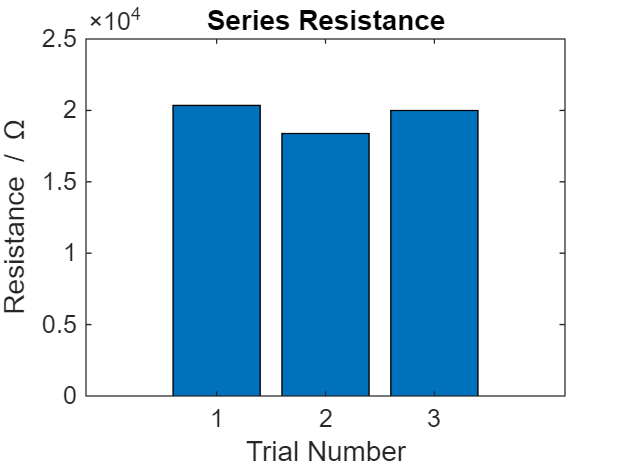

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Allocate Matracies
F_meas1 = zeros(1,Nfiles);
F_meas2 = zeros(1,Nfiles);
VoltageMeasured = zeros(1,Nfiles);
I_meas = zeros(1,Nfiles);
phi1 = zeros(1,Nfiles);
phi2 = zeros(1,Nfiles);
Z_off = zeros(1,Nfiles);
R_off = zeros(1,Nfiles);
C_off = zeros(1,Nfiles);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% Create sin curve fits for the voltage and current curves
for n = 1:Nfiles
    [xData, yData] = prepareCurveData(Time(n,:), Voltage(n,:));

    % Set up fittype and options.
    ft = fittype( 'sin1' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [-Inf 0 -Inf];

    % Fit model to data.
    fitresult = fit( xData, yData, ft, opts );
    Vcoeff = coeffvalues(fitresult);% Find coefficients from fit results
    a1 = Vcoeff(1);
    b1 = Vcoeff(2);
    c1 = Vcoeff(3);
    F_meas1(n) = b1/2/pi(); % Measured Frequency in Hz
    
    
    
    % Take Periods  of the data (Important for Duty cycle meaasurments)

    % Find Index points to truncate the input Voltage to 1 full Period
    [~,index1(n)] = min(abs(Time(n,:) - 0/(4*F_meas1(n))));
    [~,index2(n)] = min(abs(Time(n,:) - 4/(4*F_meas1(n))));
    TruncIndex(n) = abs(index1(n) - index2(n));
    %TTruncOff = Time(n,index1(n):index2(n));
    %VTruncOff = Voltage(n,index1(n):index2(n));
    %ITruncOff = Current(n,index1(n):index2(n));
    
    TTruncOff = Time(n,:);
    VTruncOff = Voltage(n,:);
    ITruncOff = Current(n,:);
    %ITruncOff = ITruncOff - mean(ITruncOff);

    
    
    
    % Refit Voltage after truncating
     [xData, yData] = prepareCurveData(TTruncOff,VTruncOff);

    % Set up fittype and options.
    ft = fittype( 'sin1' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [-Inf 0 -Inf];

    % Fit model to data.
    fitresult = fit( xData, yData, ft, opts );
    Vcoeff = coeffvalues(fitresult);% Find coefficients from fit results
    a1 = Vcoeff(1);
    b1 = Vcoeff(2);
    c1 = Vcoeff(3);
    F_meas1(n) = b1/2/pi(); % Measured Frequency in Hz
    VoltageMeasured(n) = a1; % Voltage Amplitude Measured in V
    phi1(n) = c1; % Phase shift

    
    
    
    
    
    % Current Fitting%%%%%%%%
    % Fit Current Wave form to Sin Wave
    [xData, yData] = prepareCurveData(TTruncOff, ITruncOff);

    % Fit model to data.
    fitresult = fit( xData, yData, ft, opts );
    Icoeff = coeffvalues(fitresult);% Find coefficients from fit results
    a2 = Icoeff(1);
    b2 = Icoeff(2);
    c2 = Icoeff(3);
    F_meas2(n) = b2/2/pi(); % Measured Frequency in Hz
    I_meas(n) = a2; % Current Amplitude Measured in A
    phi2(n) = c2; % Phase shift
    PhaseShiftTime(n) = (1/F_meas1(n)/360)*rad2deg(abs(phi2(n) - phi1(n)-(pi/2)));
    
  
    
    % Take the coefficients and simulate
    w = F_meas1(n)*2*pi; % Find angular frequency
    vi = VoltageMeasured(n)*exp(1i*(pi/2 - (w*Time(n,:)+phi1(n)))); % Simulate Voltage waveform
    ii = I_meas(n)*exp(1i*(pi/2 -(w*Time(n,:)+phi2(n)))); % Simulate Current Waveform
    Z_off(n) = mean(vi./ii); % Find impedence (Should be constant complex number)
    err = std(vi./ii); % Checks to make sure the impedence is close to constant
    if err >= 10^-7
        disp('WARNING std of Z is too high')
    end

    R_off(n) = real(Z_off(n));
    C_off(n) = 1/(imag(Z_off(n))*w);
if n ~=Nfiles
clear VTruncOff ITruncOff TTruncOff
end

end
% Find error in resistance measurment
R_off_err = std(R_off);
C_off_err = std(C_off);
% R_off = 10000* ones(length(R_off));
% Plot Resistance
figure
bar(R_off)
xlabel('Trial Number')
ylabel('Resistance / \Omega')
title('Series Resistance')

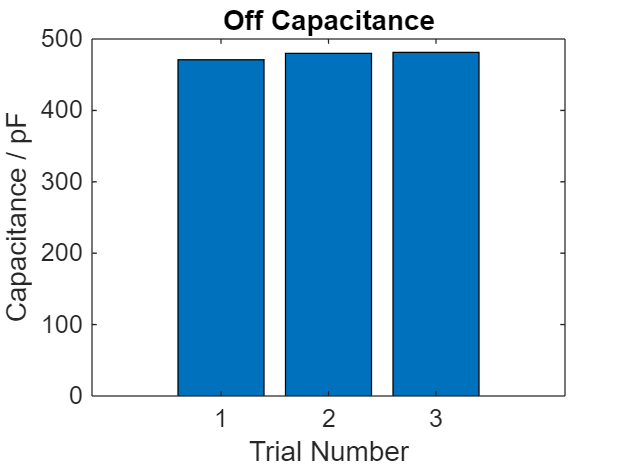

% Plot off Capacitance
figure
bar(C_off*10^12)
xlabel('Trial Number')
ylabel('Capacitance / pF')
title('Off Capacitance')

disp(['Average Equivalent Series Resistance = ',num2str(round(mean(R_off)*100)/100),' Ohms +- ',num2str(round(mean(R_off_err)*100)/100),' Ohms'])

Average Equivalent Series Resistance = 19574.32 Ohms +- 1046.9 Ohms


disp(['Average Off Capacitance = ',num2str(round(mean(C_off)*10^14)/100),' pF +- ',num2str(round(mean(C_off_err)*10^14)/100),' pF'])

Average Off Capacitance = 477.35 pF +- 5.6 pF


% plotexample simulated results 
figure 
plot(TTruncOff,VTruncOff); hold on; plot(TTruncOff,vi)

ylabel('Voltage / V')
yyaxis right
plot(TTruncOff,ITruncOff); hold on; plot(TTruncOff,ii)

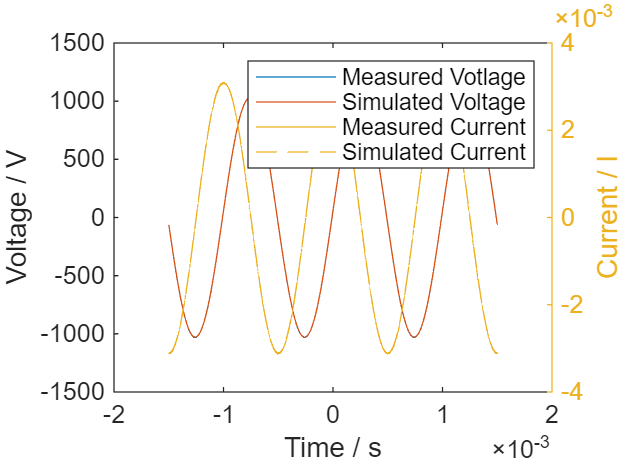

ylabel('Current / I')
xlabel('Time / s')
legend('Measured Votlage','Simulated Voltage','Measured Current','Simulated Current')

% This section is reserved to create Warnings and code Breaks if a results
% is obtained that is not expected
ResistanceAverage = mean(R_off);
CapacitanceAverage = mean(C_off);
ZZ = Z_off;

% Clear Variables that are not needed any more (Comment out this line to help debugging)
% clear Icoeff  a1 b1 c1 vi ii w a2 b2 c2 ft gof Imeas  phi1 phi2 xData yData Z_off opts Voltage Current


## Plasma On Data Read In

Open Directory and read in data same method as in section 1

## Section - 3 Plasma On Data Read In

if strcmp(PathOn,'') == 1
    PathOn = uigetdir('/Users/duncantrosan/Documents/MATLAB/Data/2022','Choose Plasma Off Directory'); % Put your data directory here to make dinding the files easier.
end
[Time,Channel1,Channel2] = OscopeReadin(PathOn);

Files Read In
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_000_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_001_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_002_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_003_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_004_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_005_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_006_ALL.csv
E:\MATLAB\Data\SDBDModelingProject\VoltageandCurrent\2025\1600 Hz\bighex\bighex\vsweep\PlasmaOn\bghexvsweep_007_ALL.csv
E:\MATLAB\Data\SDBDModelin

[Nfiles,Npoints] = size(Time); % Find the length and number of files from Oscope readin
% Load UI for changing input parameters
if VerifyParameters == 1
else
    VoltageOn = Channel1*500; % Lab amplifier is 500x
    CurrentOn = Channel2*6/1000;% Lab amplifer 1 V = 6mA
end
clear Channel1 Channel2 PathOff


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Allocate Matracies
Ub_pos = zeros(1,Nfiles);
Ub_neg = zeros(1,Nfiles);
Ub_avg = zeros(1,Nfiles);
F_Meas_On = zeros(1,Nfiles);
Cdis = zeros(1,Nfiles);
Vign_pos = zeros(1,Nfiles);
Urign_pos = zeros(1,Nfiles);
Vign_neg = zeros(1,Nfiles);
Urign_neg = zeros(1,Nfiles);
Ton = zeros(1,Nfiles);
Ton_pos = zeros(1,Nfiles);
Ton_neg = zeros(1,Nfiles);
OffIndex = zeros(1,Nfiles);
VoltagePhase = zeros(1,Nfiles);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% if statement to determine to use hardcoded device parameter and area
if DeviceSelection == 0
    Area_Device = 5389/1000^2; % m^2
    Area_Electrode = .00379; % m^2
    Electrode_Parameter = 1269.7/1000; % m
elseif DeviceSelection == 1
    % Open device Selection UI (Still being made)
end



% Start Calculations
for n = 1:Nfiles
    % Fit Voltage to a sin curve This is done so that a derivitive can be taken
    % without substantal amount of error.
    % Measured Voltage
    [xData, yData] = prepareCurveData( Time(n,:), VoltageOn(n,:) );
    t = Time(n,:);
    % Set up fittype and options.
    ft = fittype( 'sin1' );
    opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
    opts.Display = 'Off';
    opts.Lower = [-Inf 0 -Inf];

    % Fit model to data.
    [fitresult] = fit( xData, yData, ft, opts );
    Vcoeff = coeffvalues(fitresult);
    a1 = Vcoeff(1); % Equal to the Voltage amplitude
    b1 = Vcoeff(2); % Equal to the angular frequency
    c1 = Vcoeff(3); % Phase of the wave


    F_Meas_On(n,1) = b1/2/pi(); % Very important for rest of the anlysis
    VoltageMeasured(n) = a1; % Important as the measured voltage is not exactly the voltage input.
    % Find the frequency the closely matches the frequency of the off
    % measurments Really helpful for frequency sweeps
    
    VoltagePhase(n) = c1;
    [~,OffIndex(n)] = min(abs(F_Meas_On(n) - F_meas1));
    if  min(abs(F_Meas_On(n) - F_meas1)) >= 0.05*F_meas1
        disp('Warning there is no off frequency measurment that matches the measured on frequency')
    end
end

Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on frequency
Warning there is no off frequency measurment that matches the measured on fr

Ncells = length(Time);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% Allocate Matracies
Dielectric_capacitance = zeros(Nfiles,Ncells);
GapVoltage = zeros(Nfiles,Ncells);
PlasmaResistance = zeros(Nfiles,Ncells);
PositiveHalfwavePlasmaResistance = zeros(Nfiles);
NegativeHalfwavePlasmaResistance = zeros(Nfiles);
AveragePlasmaResistance = zeros(Nfiles);
index1 = zeros(1,Nfiles);
index2 = zeros(1,Nfiles);
TruncIndex = zeros(1,Nfiles);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


%% Deleate this
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for n = 1:Nfiles
    % Find Index points to truncate the input Voltage to 1 full Period
    [~,index1(n)] = min(abs(Time(n,:) + 0.5/(4*F_Meas_On(n))));
    [~,index2(n)] = min(abs(Time(n,:) - 3.5/(4*F_Meas_On(n))));
    TruncIndex(n) = abs(index1(n) - index2(n));
end
% Allocate Truncated Matracies
VTrunc = zeros(Nfiles,max(TruncIndex));
ITrunc = zeros(Nfiles,max(TruncIndex));
TTrunc = zeros(Nfiles,max(TruncIndex));
QTruncTemp = zeros(1,max(TruncIndex));
QTrunc = zeros(Nfiles,max(TruncIndex));
QConstant = zeros(1,Nfiles);
VoltageDrop = zeros(Nfiles,max(TruncIndex));
UrTrunc = zeros(Nfiles,max(TruncIndex));
TotalEnergyDeposited = zeros(1,Nfiles);
PlasmaEnergyDeposited = zeros(1,Nfiles);
UrMeasured = zeros(1,Nfiles);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n = 1:Nfiles
    for i = 1:TruncIndex(n)
        % This helps me keep track of things by makeing these vectors
        % instead of matracies
        % These are slso truncated to one period
        VTrunc(n,i) = VoltageOn(n,i+index1(n));
        ITrunc(n,i) = CurrentOn(n,i+index1(n));
        TTrunc(n,i) = Time(n,i+index1(n));
    end
    % Get rid of DC bias
    ITrunc(n,1:TruncIndex(n)) = ITrunc(n,1:TruncIndex(n)) - mean(ITrunc(n,1:TruncIndex(n)));
    % Find Truncated Q and then find the constant to give center the y axis
    % of the Q at 0
    QConstant(n) = trapz(TTrunc(n,1:TruncIndex(n)),ITrunc(n,1:TruncIndex(n)))./TruncIndex(n);
    % Including Q constant
    % QTruncTemp = cumtrapz(TTrunc(n,1:TruncIndex(n)),ITrunc(n,1:TruncIndex(n)) - QConstant(n) );
    % Exluding QConstant
    QTruncTemp = cumtrapz(TTrunc(n,1:TruncIndex(n)),ITrunc(n,1:TruncIndex(n)) );

    % Fill in Q trunc
    for i = 1:TruncIndex(n)
        QTrunc(n,i) = QTruncTemp(i);
        UrTrunc(n,i) = VTrunc(n,i) - ITrunc(n,i).*R_off(OffIndex(n));
    end
    % Center Charge to the midway point
    QTrunc(n,1:TruncIndex(n)) = QTrunc(n,1:TruncIndex(n)) - mean(QTrunc(n,1:TruncIndex(n)));
    % Find the Energy Deposited per Period
    TotalEnergyDeposited(n) = trapz(TTrunc(n,1:TruncIndex(n)),VTrunc(n,1:TruncIndex(n)).*ITrunc(n,1:TruncIndex(n)));
    PlasmaEnergyDeposited(n) = trapz(TTrunc(n,1:TruncIndex(n)),VTrunc(n,1:TruncIndex(n)).*ITrunc(n,1:TruncIndex(n)) - (R_off(OffIndex(n)) * (ITrunc(n,1:TruncIndex(n))).^2));
    % Find the Ur Measured Throughout the Discharge
    UrMeasured(n) = max(UrTrunc(n,:));
end
OffFreq = mean(F_meas1);
TotalPower = OffFreq .*TotalEnergyDeposited;
PlasmaPower = OffFreq .* PlasmaEnergyDeposited;

Find Plasma Ignition points

% Allocate Matracies
VoltageFitTrunc = zeros(Nfiles,max(TruncIndex));
Displacement = zeros(Nfiles,max(TruncIndex));
Discharge = zeros(Nfiles,max(TruncIndex));
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n = 1:Nfiles
    for i = 1:TruncIndex(n)
        VoltageFitTrunc(n,i) =(VoltageMeasured(n)*sin(F_Meas_On(n)*TTrunc(n,i)+VoltagePhase(n)));
    end
    SimulatedVoltage(n,:) = VoltageMeasured(n) * sin(F_Meas_On(n)*2*pi() * TTrunc(n,:)     + VoltagePhase(n) )
    DisplacementTemp = C_off(OffIndex(n))*gradient(UrTrunc(n,1:TruncIndex(n)))./gradient(TTrunc(n,1:TruncIndex(n)));

    DisplacementTemp = transpose(smooth(DisplacementTemp,SmoothWindow,'sgolay',3));

    % Save all the discharge from temp variables
    for i = 1:TruncIndex(n)
        Discharge(n,i) = ITrunc(n,i) - DisplacementTemp(i);
        Displacement(n,i) = DisplacementTemp(i);
    end
    clear DisplacmentTemp DischargeTemp
end

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484


SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 1.0e+03 *

   -0.6794   -0.6788   -0.6781   -0.6775   -0.6769   -0.6763   -0.6757   -0.6750   -0.6744   -0.6738   -0.6732   -0.6725   -0.6719   -0.6713   -0.6706   -0.6700   -0.6694   -0.6688   -0.6681   -0.6675   -0.6669   -0.6662   -0.6656   -0.6650   -0.6643   -0.6637   -0.6631   -0.6624   -0.6618   -0.6612   -0.6605   -0.6599   -0.6593   -0.6586   -0.6580   -0.6574   -0.6567   -0.6561   -0.6554   -0.6548   -0.6542   -0.6535   -0.6529   -0.6523   -0.6516   -0.6510   -0.6503   -0.6497   -0.6490   -0.6484
   -0.6792   -0.6786   -0.6779   -0.6773   -0.6767   -0.6761   -0.6754   -0.6748   -0.6742   -0.6736   -0.6729   -0.6723   -0.6717   -0.6710   -0.6704   -0.6698   -0.6692   -0.6685   -0.6679   -0.6673   -0.6666   -0.6660   -0.6654   -0.6647   -0.6641   -0.6635   -0.6628   -0.6622   -0.6616   -0.6609   -0.6603   -0.6597   -0.6590   -0.6584   -0.6578   -0.6571   -0.6565   -0.6559   -0.6552   -0.6546   -0.6539   -0.6533   -0.6527   -0.6520   -0.6514   -0.6507   -0.650

SimulatedVoltage = 51×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 52×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 53×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 54×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 55×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 56×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 57×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 58×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 59×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 60×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 61×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 62×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 63×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 64×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 65×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 66×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 67×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 68×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 69×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 70×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 71×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 72×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 73×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 74×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 75×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 76×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 77×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 78×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 79×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 80×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 81×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 82×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 83×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 84×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 85×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 86×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 87×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 88×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 89×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 90×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 91×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 92×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

SimulatedVoltage = 93×7813
 -679.3927 -678.7705 -678.1480 -677.5250 -676.9015 -676.2777 -675.6534 -675.0286 -674.4034 -673.7778 -673.1517 -672.5253 -671.8983 -671.2710 -670.6432 -670.0149 -669.3863 -668.7572 -668.1276 -667.4977 -666.8673 -666.2365 -665.6052 -664.9735 -664.3414 -663.7089 -663.0759 -662.4425 -661.8087 -661.1744
 -679.1739 -678.5514 -677.9284 -677.3051 -676.6812 -676.0570 -675.4323 -674.8072 -674.1816 -673.5556 -672.9291 -672.3023 -671.6749 -671.0472 -670.4190 -669.7904 -669.1614 -668.5319 -667.9020 -667.2716 -666.6408 -666.0096 -665.3780 -664.7459 -664.1134 -663.4805 -662.8471 -662.2134 -661.5791 -660.9445
 -678.8837 -678.2612 -677.6383 -677.0149 -676.3910 -675.7668 -675.1420 -674.5169 -673.8913 -673.2653 -672.6388 -672.0120 -671.3846 -670.7569 -670.1287 -669.5001 -668.8710 -668.2415 -667.6116 -666.9812 -666.3504 -665.7192 -665.0876 -664.4555 -663.8230 -663.1901 -662.5567 -661.9229 -661.2887 -660.6540
 -866.2806 -865.5140 -864.7468 -863.9790 -863.2108 -862.4419 -861.6725

% Allocate Matracies
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
LogicThreshold = ones(1,Nfiles);
QPlasmaOnPositive = zeros(Nfiles,max(TruncIndex));
VPlasmaOnPositive  = zeros(Nfiles,max(TruncIndex));
TPlasmaOnPositive  = zeros(Nfiles,max(TruncIndex));
QPlasmaOnNegative  = zeros(Nfiles,max(TruncIndex));
QPlasmaOffPositive  = zeros(Nfiles,max(TruncIndex));
QPlasmaOffNegative  = zeros(Nfiles,max(TruncIndex));
VPlasmaOnNegative  = zeros(Nfiles,max(TruncIndex));
VPlasmaOffPositive  = zeros(Nfiles,max(TruncIndex));
VPlasmaOffNegative  = zeros(Nfiles,max(TruncIndex));
TPlasmaOnNegative  = zeros(Nfiles,max(TruncIndex));
TPlasmaOffPositive  = zeros(Nfiles,max(TruncIndex));
TPlasmaOffNegative  = zeros(Nfiles,max(TruncIndex));
UrPlasmaOnPositive = zeros(Nfiles,max(TruncIndex));
UrPlasmaOnNegative = zeros(Nfiles,max(TruncIndex));
UrPlasmaOffPositive = zeros(Nfiles,max(TruncIndex));
UrPlasmaOffNegative = zeros(Nfiles,max(TruncIndex));
point1index = zeros(1,Nfiles);
point2index = zeros(1,Nfiles);
point3index = zeros(1,Nfiles);
point4index = zeros(1,Nfiles);
PlasmaOffPositiveLength = zeros(1,Nfiles);
PlasmaOffNegativeLength = zeros(1,Nfiles);
PlasmaOnPositiveLength = zeros(1,Nfiles);
PlasmaOnNegativeLength = zeros(1,Nfiles);
DisPlasmaOnPositive = zeros(1,Nfiles);
DisPlasmaOnNegative = zeros(1,Nfiles);
DisPlasmaOffPositive = zeros(1,Nfiles);
DisPlasmaOffNegative = zeros(1,Nfiles);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
for n = 1:Nfiles
    % Fit lissajous figures to a pgram this parallegram will determine the
    % plasma parameters.
    % Points assuming that the oscilliscope parameters were taken as the code
    % expects
    % Point1index = Plasma off Positivve halvwave
    % Point2index = Plasma on
    % Point3index = Plasma off Negative Halvewave
    % Point4Index = Plasma on
    [point1y,point1index(n)] = max(QTrunc(n,:));
    point1x = VoltageDrop(point1index(n));
    point1t = Time(n,point1index(n));
    [point3y,point3index(n)] = min(QTrunc(n,:));
    point3x = VoltageDrop(point3index(n));
    point3t = Time(n,point3index(n));
    logickeep = 0;
    logicgoon =0;
    indexpos = 1;
    indexneg =1;
    locationneg = [];
    locationpos = [];
    % Create a threshold to determine when discharge current gets high
    % enough
    Plasma_On = zeros(1,length(VoltageDrop));
    for j = SmoothWindow+10:TruncIndex(n) % Starts at smoothwindow to eliminate smoothing artifacts to falsly trigger Plasma On Logic
        pointcheck = Discharge(n,j);
        if logickeep == 0
            if pointcheck >= ThreshInput
                locationpos= j;
                indexpos = indexpos +1 ;
                logickeep = 1;
            end
        end
        if logickeep == 1
            if pointcheck <= -ThreshInput
                locationneg= j;
                indexneg = indexneg +1 ;
                logickeep = 2;
            end
        end
    end

   if length(locationpos) >= 1 && length(locationneg) >=1
        point2index(n) = locationpos(1);
        point4index(n) = locationneg(1);
%         point2t(n) = Time(n,locationpos(1));
%         point4t(n) = Time(n,locationneg(1));


%         if length(point2t) >= 1 && length(point4t) >= 1
% 
%             %             Vign_pos(n) =  UrTrunc(locationpos(1));
%             %             Urign_pos(n) = VoltageDrop(locationpos(1));
%             %             Vign_neg(n) =  UrTrunc(locationneg(1));
%             %             Urign_neg(n) =  UrTrunc(locationneg(1));
%             if point1index <= length(TTrunc/4)
%                 [~,point1index_adj] = max(UrTrunc(round(length(ITrunc)/4):round(length(ITrunc)/4*3)));
%                 point1index_adj = point1index_adj + round(length( ITrunc)/4);
%                 point1t_adj = TTrunc(n,point1index_adj);
%                 Ton_pos(n) = min(abs(point1t_adj - point2t));
%                 if length(point2t) <= 1
%                     disp('Possible error calculating Ton_pos')
%                     disp(Ton_pos)
%                 end
%             end
%         end
        % Make sure that the negative minimum is on the third
        % halfwave and the first
        % if the average of the th first quartr wave is negative
%         if mean( ITrunc(1:round(length( ITrunc)/4))) <= 0
%             [~,point3index_adj] = min(VoltageDrop(round(length( UrTrunc)/2):end));
%             point3index_adj = point3index_adj + round(length( UrTrunc)/2);
%             point3t_adj = TTrunc(n,point3index_adj-1);
%             Ton_neg(n) = min(abs(point3t_adj - point4t));
%         else
%             Ton_neg(n) = min(abs(point3t - point4t));
%             if length(point4t) <= 1
%                 disp('Possible error calculating Ton_neg')
%                 disp(Ton_neg)
%             end
%         end
%         Ton(n) = min([Ton_pos(n), Ton_neg(n)]);
%         start1 = point2t;
%         end1 = point1t;
%         start2 = point4t;
%         end2 = point3t;

    else
        point2index(n) = 1;
        point4index(n) = 1;
        LogicThreshold(n) = 0;
    end




end
for n = 1:Nfiles
    % Fill in matracies for different parts of Lissajous figure
    % Plasma Off Positive start - point2index
    PlasmaOffPositiveLength(n) = point2index(n);
    for i = 1:point2index(n)
        QPlasmaOffPositive(n,i) = QTrunc(n,i);
        VPlasmaOffPositive(n,i) = VTrunc(n,i);
        TPlasmaOffPositive(n,i) = TTrunc(n,i);
        UrPlasmaOffPositive(n,i) = UrTrunc(n,i);
        DisPlasmaOffPositive(n,i) = Discharge(n,i);
    end

    % Plasma On Positive Halfwave point2index -- point1index
    PlasmaOnPositiveLength(n) = point1index(n) - point2index(n);
    for i = 1:point1index(n) - point2index(n)
        QPlasmaOnPositive(n,i) = QTrunc(n,i+point2index(n));
        VPlasmaOnPositive(n,i) = VTrunc(n,i+point2index(n));
        TPlasmaOnPositive(n,i) = TTrunc(n,i+point2index(n));
        UrPlasmaOnPositive(n,i) = UrTrunc(n,i+point2index(n));
        DisPlasmaOnPositive(n,i) = Discharge(n,i+point2index(n));
    end
    % Plasma Off Negative point1index -- point4index
    PlasmaOffNegativeLength(n) = point4index(n) - point1index(n);
    for i = 1:point4index(n) - point1index(n)
        QPlasmaOffNegative(n,i) = QTrunc(n,i+point1index(n));
        VPlasmaOffNegative(n,i) = VTrunc(n,i+point1index(n));
        TPlasmaOffNegative(n,i) = TTrunc(n,i+point1index(n));
        UrPlasmaOffNegative(n,i) = UrTrunc(n,i+point1index(n));
        DisPlasmaOffNegative(n,i) = Discharge(n,i+point1index(n));
    end
    % Plasma On Negative point4index -- point3index
    PlasmaOnNegativeLength(n) = point3index(n) - point4index(n);
    for i = 1:point3index(n) - point4index(n)
        QPlasmaOnNegative(n,i) = QTrunc(n,i+point4index(n));
        VPlasmaOnNegative(n,i) = VTrunc(n,i+point4index(n));
        TPlasmaOnNegative(n,i) = TTrunc(n,i+point4index(n));
        UrPlasmaOnNegative(n,i) = UrTrunc(n,i+point4index(n));
        DisPlasmaOnNegative(n,i) = Discharge(n,i+point4index(n));
    end


end
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Alternative Method to find Cd Without fitting to functions
for n = 1:Nfiles
    OffCapacitanceAlt(n) = ((QPlasmaOffPositive(n,PlasmaOffPositiveLength(n))-QPlasmaOffPositive(n,1))/(UrPlasmaOffPositive(n,PlasmaOffPositiveLength(n))-UrPlasmaOffPositive(n,1)));
    %QpPlasmaOnPositiveAlt(n,:) = QPlasmaOnPositive(n,:) - UrPlasmaOnPositive(n,:) .* OffCapacitanceAlt(n);
    %OnCapacitanceAlt(n) = ((QpPlasmaOnPositiveAlt(n,PlasmaOffPositiveLength(n))-QpPlasmaOnPositiveAlt(n,1)))/(UrPlasmaOffPositive(n,PlasmaOffPositiveLength(n))-UrPlasmaOffPositive(n,1));
end


## Section - 5 Take Truncated Plasma On and Off Values And Fit to Equations

% Truncated On and Off Cycle
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%% Alocate Matracies
PlasmaOnPositiveA = zeros(1,Nfiles);
PlasmaOnPositiveB = zeros(1,Nfiles);
PlasmaOnPositiveC = zeros(1,Nfiles);
PlasmaOnNegativeA = zeros(1,Nfiles);
PlasmaOnNegativeB = zeros(1,Nfiles);
PlasmaOnNegativeC = zeros(1,Nfiles);
PlasmaOffPositiveA = zeros(1,Nfiles);
PlasmaOffPositiveB = zeros(1,Nfiles);
PlasmaOffNegativeA = zeros(1,Nfiles);
PlasmaOffNegativeB = zeros(1,Nfiles);
PlasmaOnPositiveFit = zeros(Nfiles,max(TruncIndex));
PlasmaOffPositiveFit = zeros(Nfiles,max(TruncIndex));
PlasmaOnNegativeFit = zeros(Nfiles,max(TruncIndex));
PlasmaOffNegativeFit = zeros(Nfiles,max(TruncIndex));
QpPlasmaOnNegative = zeros(Nfiles,max(TruncIndex));
QpPlasmaOnPositive =  zeros(Nfiles,max(TruncIndex));
QpTrunc = zeros(Nfiles,max(TruncIndex));
AveragePlasmaResistancePositive  = zeros(1,Nfiles);
AveragePlasmaResistanceNegative = zeros(1,Nfiles);
UdTrunc = zeros(Nfiles,max(TruncIndex));
UgTrunc = zeros(Nfiles,max(TruncIndex));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Take on and off cycles fit off cycles to line and On cycles to quadratics
for n = 1:Nfiles
    clear XData YData

    % Fit the OFF cycle
    % Plasma Off Negagtive
    if PlasmaOffNegativeLength(n) >= 5
        XData = transpose(UrPlasmaOffNegative(n,1:PlasmaOffNegativeLength(n)));
        YData = transpose(QPlasmaOffNegative(n,1:PlasmaOffNegativeLength(n)));
        opts = fitoptions( 'Method', 'LinearLeastSquares' );
        opts.Upper = [Inf Inf];
        [fitresult, ~] = fit( XData, YData, 'poly1', opts );
        A = coeffvalues(fitresult);
        PlasmaOffNegativeA(n) = A(1);
        PlasmaOffNegativeB(n) = A(2);
        clear A B XData YData opts
    end
    % Plasma Off Positve
    if PlasmaOffPositiveLength(n) >= 5
        XData = transpose(UrPlasmaOffPositive(n,1:PlasmaOffPositiveLength(n)));
        YData = transpose(QPlasmaOffPositive(n,1:PlasmaOffPositiveLength(n)));
        opts = fitoptions( 'Method', 'LinearLeastSquares' );
        opts.Upper = [Inf Inf];
        [fitresult, ~] = fit( XData, YData, 'poly1', opts );
        A = coeffvalues(fitresult);
        PlasmaOffPositiveA(n) = A(1);
        PlasmaOffPositiveB(n) = A(2);
        clear A B XData YData opts
    end
    % Find Qp using the fit from the off sections
    QpPlasmaOnNegative(n,:) = QPlasmaOnNegative(n,:) - UrPlasmaOnNegative(n,:) .* PlasmaOffNegativeA(n);
    QpPlasmaOnPositive(n,:) = QPlasmaOnPositive(n,:) - UrPlasmaOnPositive(n,:) .* PlasmaOffNegativeA(n);
    QpTrunc(n,:) = QTrunc(n,:) - UrTrunc(n,:) * PlasmaOffNegativeA(n);
    % Fit the ON Cycle
    XData = transpose(UrPlasmaOnPositive(n,1:PlasmaOnPositiveLength(n)));
    YData = transpose(QpPlasmaOnPositive(n,1:PlasmaOnPositiveLength(n)));
    if PlasmaOnPositiveLength(n) >= 5
        opts = fitoptions( 'Method', 'LinearLeastSquares' );
        opts.Upper = [Inf Inf];
        [fitresult, B1] = fit( XData, YData, 'poly1', opts );
        A = coeffvalues(fitresult);
        PlasmaOnPositiveA(n) = A(1);
        PlasmaOnPositiveB(n) = A(2);
        clear A B XData YData opts
    end
    % Plasma ON Negative
    if PlasmaOnNegativeLength(n) >= 5
        XData = transpose(UrPlasmaOnNegative(n,1:PlasmaOnNegativeLength(n)));
        YData = transpose(QpPlasmaOnNegative(n,1:PlasmaOnNegativeLength(n)));
        opts = fitoptions( 'Method', 'LinearLeastSquares' );
        opts.Upper = [Inf Inf];
        [fitresult, B2] = fit( XData, YData, 'poly1', opts );
        A = coeffvalues(fitresult);
        PlasmaOnNegativeA(n) = A(1);
        PlasmaOnNegativeB(n) = A(2);
        clear A B XData YData
    end
    UdTrunc(n,:) = QpTrunc(n,:) ./ PlasmaOnPositiveA(n);
    UgTrunc(n,:) = UrTrunc(n,:) - UdTrunc(n,:);
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% Fit Data and find Gap Voltage during the On Phase
for n = 1:Nfiles
    for i = 1:PlasmaOnPositiveLength(n)
        PlasmaOnPositiveFit(n,i) = UrPlasmaOnPositive(n,i) * PlasmaOnPositiveA(n) + PlasmaOnPositiveB(n);
        UdPlasmaOnPositive(n,i) = QpPlasmaOnPositive(n,i) / PlasmaOnPositiveA(n);
        UgPlasmaOnPositive(n,i) = UrPlasmaOnPositive(n,i) - UdPlasmaOnPositive(n,i);
    end
    for i = 1:PlasmaOnNegativeLength(n)
        PlasmaOnNegativeFit(n,i) = UrPlasmaOnNegative(n,i) * PlasmaOnNegativeA(n) + PlasmaOnNegativeB(n);
        UdPlasmaOnNegative(n,i) = QpPlasmaOnNegative(n,i) / PlasmaOnNegativeA(n);
        UgPlasmaOnNegative(n,i) = UrPlasmaOnNegative(n,i) - UdPlasmaOnNegative(n,i);
    end
    % Fit The plasma Charge on the the on leg

    for i = 1:PlasmaOffNegativeLength(n)
        PlasmaOffNegativeFit(n,i) = UrPlasmaOffNegative(n,i) * PlasmaOffNegativeA(n) + PlasmaOffNegativeB(n);
    end
    for i = 1:PlasmaOffPositiveLength(n)
        PlasmaOffPositiveFit(n,i) = UrPlasmaOffPositive(n,i) * PlasmaOffPositiveA(n) +  PlasmaOffPositiveB(n);
    end
    UgAveragePositive(n) = mean(UgPlasmaOnPositive(n,1:PlasmaOnPositiveLength(n)));
    %UgAverageNegative(n) = mean(UgPlasmaOnNegative(n,1:PlasmaOnNegativeLength(n)));
    UgMiddlePositive(n) = UgPlasmaOnPositive(n,round(PlasmaOnPositiveLength(n)/2));
    %UgMiddleNegative(n) = UgPlasmaOnNegative(n,round(PlasmaOnNegativeLength(n)/2));
end

Index in position 1 exceeds array bounds. Index must not exceed 1.

## Section - 6 Find Electric Field, C', V0, and C0 From Fitted Constants


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

ChargeDerivitive = zeros(Nfiles,max(TruncIndex));
PlasmaChargeDerivitive = zeros(Nfiles,max(TruncIndex));
ElectrodeCapacitancePositive = PlasmaOffPositiveA;
ElectrodeCapacitanceNegative = PlasmaOffNegativeA;
DielectricCapacitancePositive = PlasmaOnPositiveA;
DielectricCapacitanceNegative = PlasmaOnNegativeA;
PlasmaAreaPositive = DielectricCapacitancePositive/CapacitancePerArea;
PlasmaAreaNegative = DielectricCapacitanceNegative/CapacitancePerArea;
PowerIns = Discharge.*UgTrunc;
DisplacementSim = zeros(Nfiles,max(TruncIndex));
DischargeSim = zeros(Nfiles,max(TruncIndex));
for n = 1:Nfiles
EnergyIns(n) = trapz(TTrunc(n,:),PowerIns(n,:));
PlasmaResistancePositive(n) = UgAveragePositive(n)./mean(DisPlasmaOnPositive(n,1:PlasmaOnPositiveLength(n)));
DisplacementSim(n,1:TruncIndex(n)) = PlasmaOffNegativeA(n) .* gradient(SimulatedVoltage(n,1:TruncIndex(n)))./gradient(TTrunc(n,1:TruncIndex(n)));
DischargeSim(n,1:TruncIndex(n)) = ITrunc(n,1:TruncIndex(n)) - DisplacementSim(n,1:TruncIndex(n));
%PlasmaResistanceNegative(n) = UgAveragePositive(n)./mean(DisPlasmaOnNegative(n,1:PlasmaOnNegativeLength(n)));
% ChargeDerivitive
end

for n = 1:Nfiles
[~,Urfit] = spaps(TTrunc(n,1:TruncIndex(n)),UrTrunc(n,1:TruncIndex(n)),0.09);
[~,QFit] = spaps(TTrunc(n,1:TruncIndex(n)),QpTrunc(n,1:TruncIndex(n)).*10^9,0.09);
QFit = QFit/10^9;
dqdv = gradient(QTrunc(n,1:TruncIndex(n)))./gradient(Urfit);
clear Urfit QFit
% dqdv = gradient(downsample(QTrunc(n,1:TruncIndex(n)),10))./gradient(downsample(UrTrunc(n,1:TruncIndex(n)),10));
%dqdv = gradient(QTrunc(n,1:TruncIndex(n)))./gradient(UrTrunc(n,1:TruncIndex(n)));

df = 1/(TTrunc(n,2) - TTrunc(n,1));
dqdv(dqdv<=-10*10^-8) = -10*10^-8; % Set large asymptotes equal to some maximum value
dqdv(dqdv>=10*10^-8) = 10*10^-8; % Set large asymptotes equal to some maximum value
%ChargeDerivitive(n,1:TruncIndex(n)) = smooth(dqdv,SmoothWindow,'sgolay',4); % Smoothes out most of the noise from the;
% ChargeDerivitive(n,1:TruncIndex(n)) = smooth(dqdv(1:TruncIndex(n)),SmoothWindow,'sgolay',3); % Smoothes out most of the noise from the;
%ChargeDerivitive(n,1:TruncIndex(n)) = lowpass(dqdv,5000,df); % Smoothes out most of the noise from the;
ChargeDerivitive(n,1:TruncIndex(n)) = dqdv;
% Now do the same for plasma charge 
%dqdv = gradient(QpTrunc(n,1:TruncIndex(n)))./gradient(Urfit);
%ChargeDerivitive(n,1:TruncIndex(n)) = smooth(dqdv(1:TruncIndex(n)),SmoothWindow,'sgolay',3); % Smoothes out most of the noise from the;

%dqdv(dqdv<=-1*10^-9) = -10^-9; % Set large asymptotes equal to some maximum value
%dqdv(dqdv<=-1*10^-9) = -10^-9; % Set large asymptotes equal to some maximum value
%dqdv(dqdv>=1*10^-9) = 10^-9; % Set large asymptotes equal to some maximum value
PlasmaChargeDerivitive(n,1:TruncIndex(n)) = smooth(dqdv(1:TruncIndex(n)),SmoothWindow,'sgolay',5); % Smoothes out most of the noise from the;
clear dqdv
end
% 
% % Get Plasma Extent from Plasma Area
% Aside = 0.0896; % m
% Bside = 0.0237; % m
% PlasmaExtentPositive = -(Aside+Bside)+sqrt((Aside+Bside)^2 +PlasmaAreaPositive);
% PlasmaExtentNegative = -(Aside+Bside)+sqrt((Aside+Bside)^2 +PlasmaAreaNegative);
% %EFieldPositive = UgAveragePositive./PlasmaExtentPositive;
% %EFieldNegative = UgAverageNegative./PlasmaExtentNegative;
% n0 = 2.686 *10^25;
% %TownsendPositive = EFieldPositive/n0/(10^-21);
% %TownsendNegative = EFieldNegative/n0/(10^-21);
% EfieldCorrect = UgAveragePositive/Thickness/n0/10^-21;

## Section - 7 Plotting

%% Plot the data from the truncated values to make sure truncation is
% working
% figure
% plot(UrPlasmaOnPositive(30,1:PlasmaOnPositiveLength(30)),QPlasmaOnPositive(30,1:PlasmaOnPositiveLength(30)),'Color','red','LineWidth',3); hold on
% plot(UrPlasmaOffNegative(30,1:PlasmaOffNegativeLength(30)),QPlasmaOffNegative(30,1:PlasmaOffNegativeLength(30)),'Color','green','LineWidth',3); hold on
% plot(UrPlasmaOnNegative(30,1:PlasmaOnNegativeLength(30)),QPlasmaOnNegative(30,1:PlasmaOnNegativeLength(30)),'Color','black','LineWidth',3); hold on
% plot(UrPlasmaOffPositive(30,1:PlasmaOffPositiveLength(30)),QPlasmaOffPositive(30,1:PlasmaOffPositiveLength(30)),'Color','blue','LineWidth',3); hold on
% xlabel('Voltage Drop Through Device / V')
% ylabel('Charge Through Device / C')
% set(gcf,'Visible','on')

DischargeGraphing = 1;
if DischargeGraphing == 1
    for k = 1:Nfiles
        figure
        plot(TTrunc(k,:),Discharge(k,:),'LineWidth',2); hold on ; yyaxis right
        ylabel('Current / A')
        plot(TTrunc(k,:),VTrunc(k,:),'LineWidth',2); hold on
        xline(TTrunc(k,point1index(k)),'Color','red');
        xline(TTrunc(k,point2index(k)),'Color','blue');
        xline(TTrunc(k,point3index(k)),'Color','green');
        xline(TTrunc(k,point4index(k)),'Color','black');
        ylabel('Voltage / V')
        xlabel('Time / s')
        title(['Discharge at ',num2str(round(VoltageMeasured(k))),' Volts'])
        set(gcf,'Visible','on')
    end
end


figure;
DischargeGraphing = 1;
if DischargeGraphing == 1
    i = 1;
    AAA  = linspace(0,Nfiles*6-6,Nfiles);
    for k = 1:Nfiles
        plot(TTrunc(k,1:TruncIndex(k)), DischargeSim(k,1:TruncIndex(k)),'LineWidth',2); hold on ;
        ylabel('Current / A')
        xlabel('Time / s')
        title(['Change In Current During 15 Minute Treatment'])
        set(gcf,'Visible','on')
        Labels{i} = [num2str(round(AAA(k),0)), ' sec'];
        i = i+1;
    end
    Labels{i} = 'Applied Voltage'
    legend(Labels,'Location','SouthWest')
end
yyaxis right 
k = Nfiles-1;
plot(TTrunc(k,1:TruncIndex(k)), VTrunc(k,1:TruncIndex(k)),'LineWidth',2); hold on ;
ylabel('Voltage / V')
ylim([-2500,2500]);
% 
% figure
% scatter(VoltageMeasured,PlasmaOnPositiveA); hold on ;
% %scatter(VoltageMeasured,PlasmaOnNegativeA);
% ylabel('Results from Fit (A)')
% yyaxis right; 
% scatter(VoltageMeasured,PlasmaOnPositiveC);
% %scatter(VoltageMeasured,PlasmaOnNegativeC);
% ylabel('Results from Fit (C)')
% xlabel('Measured Voltage / V')
% set(gcf,'Visible','on')
% 



% Plot Electrode Parameters
ParameterGraphing = 0;
if ParameterGraphing == 1
    figure
    scatter(VoltageMeasured(10:end),ElectrodeCapacitancePositive(10:end)*10^12); hold on
    scatter(VoltageMeasured(10:end),CPrimePositive(10:end)*10^12)
    yline(CapacitanceAverage*10^12);
    scatter(VoltageMeasured(10:end),PlasmaOffPositiveA(10:end)*10^12)
    title('Positive Electrode Capacitance and Non Ideal Capacitance')
    ylabel('Capacitance / pF')
    xlabel('Measured Voltage Amplitude / V')
    legend('Electrode Capacitance','NonIdealCapacitance','Off Capacitance','Off Cycle Capacitance','Location','SouthEast')
    set(gcf,'Visible','on')
    
        
    figure
    scatter(VoltageMeasured(10:end),ElectrodeCapacitanceNegative(10:end)*10^12); hold on
    scatter(VoltageMeasured(10:end),CPrimeNegative(10:end)*10^12)
    yline(CapacitanceAverage*10^12);
    title('Negative Electrode Capacitance and Non Ideal Capacitance')
    ylabel('Capacitance / pF')
    xlabel('Measured Voltage Amplitude / V')
    legend('Electrode Capacitance','NonIdealCapacitance','Off Capacitance')
    set(gcf,'Visible','on')
    
    figure
    scatter(VoltageMeasured(10:end),BreakdownVoltagePositive(10:end)); hold on
    title('Positive Electrode Breakdown Voltage')
    ylabel('Breakdown Voltage / V')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
    
    figure
    scatter(VoltageMeasured(10:end),BreakdownVoltagePositive(10:end)); hold on
    title('Negative Electrode Breakdown Voltage')
    ylabel('Breakdown Voltage / V')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
    
    figure
    scatter(VoltageMeasured(10:end),AlphaPositive(10:end)/Perimeter*10^16);
    title('Positive HalfwaveAlpha Parameter')
    ylabel('Alpha / F V^-1 m^-1')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
    
       figure
    scatter(VoltageMeasured(10:end),AlphaNegative(10:end)/Perimeter*10^16);
    title('Negative Halfwave Alpha Parameter')
    ylabel('Alpha / F V^-1 m^-1')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
    
    figure
    scatter(VoltageMeasured(10:end),TownsendPositive(10:end));
    title('Positive Halfwave Electric Field')
    ylabel('Electric Field / Td')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
    
    figure
    scatter(VoltageMeasured(10:end),TownsendNegative(10:end));
    title('Negative Halfwave Electric Field')
    ylabel('Electric Field / Td')
    xlabel('Measured Voltage Amplitude / V')
    set(gcf,'Visible','on')
end

LissajousGraphing = 1;
if LissajousGraphing ==1
    % k = 30; % Value to determine which data point you want
    % Plot scatter plot of the data
    for k = 1:10:Nfiles
    figure
    scatter(downsample(UrTrunc(k,1:TruncIndex(k)),20),10^6*downsample(QTrunc(k,1:TruncIndex(k)),20),20,[0,0,1]); hold on
    %plot(UrPlasmaOffPositive(k,1:PlasmaOffPositiveLength(k)),10^6*PlasmaOffPositiveFit(k,1:PlasmaOffPositiveLength(k)),'Color','Red','LineWidth',3); hold on
    %plot(UrPlasmaOffNegative(k,1:PlasmaOffNegativeLength(k)),10^6*PlasmaOffNegativeFit(k,1:PlasmaOffNegativeLength(k)),'Color' , 'blue','LineWidth',3 );
    %plot(UrPlasmaOnPositive(k,1:PlasmaOnPositiveLength(k)),10^6*PlasmaOnPositiveFit(k,1:PlasmaOnPositiveLength(k)),'Color','black' ,'LineWidth',3);
    %plot(UrPlasmaOnNegative(k,1:PlasmaOnNegativeLength(k)),10^6*PlasmaOnNegativeFit(k,1:PlasmaOnNegativeLength(k)),'Color' , 'Green' ,'LineWidth',3);
    %title(['Lissajous Figure at ',num2str(round(VoltageMeasured(k))),' Volts'])
    ylabel('Charge / \muC')
    xlabel('Measured Voltage / V')
    set(gcf,'Visible','on')
    end
end

LissajousGraphing = 1;
if LissajousGraphing ==1
    % k = 30; % Value to determine which data point you want
    % Plot scatter plot of the data
    for k = 1:20:Nfiles
    figure
    scatter(downsample(VTrunc(k,1:TruncIndex(k)),20),downsample(QTrunc(k,1:TruncIndex(k)),20),20,[0,0,1]); hold on
    scatter(downsample(UrTrunc(k,1:TruncIndex(k)),20),downsample(QTrunc(k,1:TruncIndex(k)),20),20,[0,0,1]); hold on
    
    %plot(UrPlasmaOnPositive(k,1:PlasmaOnPositiveLength(k)),PlasmaOnPositiveFit(k,1:PlasmaOnPositiveLength(k)),'Color','black' ,'LineWidth',3);
    %plot(UrPlasmaOnNegative(k,1:PlasmaOnNegativeLength(k)),PlasmaOnNegativeFit(k,1:PlasmaOnNegativeLength(k)),'Color' , 'Green' ,'LineWidth',3);
    %title(['Lissajous Figure at ',num2str(round(VoltageMeasured(k))),' Volts'])
    ylabel('Charge / C')
    xlabel('Measured Voltage / V')
    set(gcf,'Visible','on')
    end
end
GapVoltageGraphing =1;
if GapVoltageGraphing == 1
    % k = 30; % Value to determine which data point you want
    % Plot scatter plot of the data
    figure(3001)
    i = 1;
    for k = 80:4:Nfiles
    plot(TTrunc(k,:),UgTrunc(k,:)); hold on
    ylabel('Ug / V')
    xlabel('Measured Voltage / V')
    set(gcf,'Visible','on')
    GapVoltageLegendLabels{i} = [num2str(round(AAA(k),3)), ' min'];

    GapVoltageData(2*i -1,1:TruncIndex(k)) = TTrunc(k,1:TruncIndex(k));
    GapVoltageData(2*i,1:TruncIndex(k)) = UgTrunc(k,1:TruncIndex(k));
    i = i+1;
    end
    legend(GapVoltageLegendLabels)
end

dQdVGraphing =1;
if dQdVGraphing == 1
    % k = 30; % Value to determine which data point you want
    % Plot scatter plot of the data
    figure
    i = 1;
    for k = 1:12:Nfiles
    plot(VTrunc(k,1:TruncIndex(k))/VoltageMeasured(k),ChargeDerivitive(k,1:TruncIndex(k))*10^12); hold on
    ylabel('Charge Derivitive / pF')
    xlabel('Time / s')
    set(gcf,'Visible','on')
    GapVoltageLegendLabels{i} = [num2str(k), ' min'];
    i = i+1;
    end
    legend()
end

dQdVGraphing =1;
if dQdVGraphing == 1
    % k = 30; % Value to determine which data point you want
    % Plot scatter plot of the data
    figure
    i = 1;
    for k = 1:16:Nfiles
    plot(TTrunc(k,1:TruncIndex(k)),ChargeDerivitive(k,1:TruncIndex(k))*10^12); hold on
    ylabel('Charge Derivitive / pF')
    xlabel('Time / s')
    set(gcf,'Visible','on')
    GapVoltageLegendLabels{i} = [num2str(VoltageMeasured(k)), ' V'];
    i = i+1;
    end
    legend(GapVoltageLegendLabels)
end



figure

%figure; 
%scatter(VoltageMeasured,EfieldCorrect);
ylabel('Reduced Elctric Field / Td')
xlabel('Applied Voltage Amplitude / V')


for n = 1:Nfiles/3
    PlasmaPowerTrip(n) = mean([PlasmaPower(3*n),PlasmaPower(3*n-1),PlasmaPower(3*n-2)]);
    VoltageMeasuredTrip(n) = mean([VoltageMeasured(3*n),VoltageMeasured(3*n-1),VoltageMeasured(3*n-2)]);
    VoltageMeasuredSTD(n) = std([VoltageMeasured(3*n),VoltageMeasured(3*n-1),VoltageMeasured(3*n-2)]);
    UrMeasuredTrip(n) = mean([UrMeasured(3*n),UrMeasured(3*n-1),UrMeasured(3*n-2)]);
    PlasmaPowerTripSTD(n) = std([PlasmaPower(3*n),PlasmaPower(3*n-1),PlasmaPower(3*n-2)]);
    VoltageMeasuredTripSTD(n) = std([VoltageMeasured(3*n),VoltageMeasured(3*n-1),VoltageMeasured(3*n-2)]);
    UrMeasuredTripSTD(n) = std([UrMeasured(3*n),UrMeasured(3*n-1),UrMeasured(3*n-2)]);
    DielectricCapacitanceTrip(n) = mean([PlasmaOnPositiveA(3*n),PlasmaOnPositiveA(3*n-1),PlasmaOnPositiveA(3*n-2)]);
    DielectricCapacitanceTripSTD(n) = std([PlasmaOnPositiveA(3*n),PlasmaOnPositiveA(3*n-1),PlasmaOnPositiveA(3*n-2)]);
    PlasmaExtentPositiveTrip(n) = mean([PlasmaExtentPositive(3*n),PlasmaExtentPositive(3*n-1),PlasmaExtentPositive(3*n-2)]);
    PlasmaExtentPositiveTripSTD(n) = std([PlasmaExtentPositive(3*n),PlasmaExtentPositive(3*n-1),PlasmaExtentPositive(3*n-2)]);
end



## Section 8 - Saving Data to File

SaveData = 0;
if SaveData == 1;
% ListName = {RunName};
Data = transpose([VoltageMeasured;DielectricCapacitancePositive;DielectricCapacitanceNegative;UgAveragePositive;UgAverageNegative;PlasmaResistancePositive;PlasmaResistanceNegative;TotalPower;PlasmaPower]);
HeaderLines = {'Measured Voltage','Postive Halfwave Dielectric Capacitance','Negative Halfwave Dielectric Capacitance','Positive Halfwave Plasma Resistance','Negative Halfwave Plasma Resistance','Total Power','Plasma Power'};
writecell(HeaderLines, SaveFileName,"Delimiter",',', "FileType", "text",'WriteMode','append');
writematrix(Data, SaveFileName, 'Delimiter', ',', 'WriteMode', 'append');
end



 OriginUgTrunc = [TTrunc(Index(1),:);UgTrunc(Index(1),:);TTrunc(Index(2),:);UgTrunc(Index(2),:);TTrunc(Index(3),:);UgTrunc(Index(3),:);TTrunc(Index(4),:);UgTrunc(Index(4),:);TTrunc(Index(5),:);UgTrunc(Index(5),:);TTrunc(Index(6),:);UgTrunc(Index(6),:)]';
 OriginVTrunc = [TTrunc(Index(1),:);VTrunc(Index(1),:);TTrunc(Index(2),:);VTrunc(Index(2),:);TTrunc(Index(3),:);VTrunc(Index(3),:);TTrunc(Index(4),:);VTrunc(Index(4),:);TTrunc(Index(5),:);VTrunc(Index(5),:);TTrunc(Index(6),:);VTrunc(Index(6),:)]';
 OriginDischarge = [TTrunc(Index(1),:);Discharge(Index(1),:);TTrunc(Index(2),:);Discharge(Index(2),:);TTrunc(Index(3),:);Discharge(Index(3),:);TTrunc(Index(4),:);Discharge(Index(4),:);TTrunc(Index(5),:);Discharge(Index(5),:);TTrunc(Index(6),:);Discharge(Index(6),:)]';
 OriginCurrent = [TTrunc(Index(1),:);ITrunc(Index(1),:);TTrunc(Index(2),:);ITrunc(Index(2),:);TTrunc(Index(3),:);ITrunc(Index(3),:);TTrunc(Index(4),:);ITrunc(Index(4),:);TTrunc(Index(5),:);ITrunc(Index(5),:);TTrunc(Index(6),:);ITrunc(Index(6),:)]';
 OriginChargeDerivitive = [TTrunc(Index(1),:);ChargeDerivitive(Index(1),:);TTrunc(Index(2),:);ChargeDerivitive(Index(2),:);TTrunc(Index(3),:);ChargeDerivitive(Index(3),:);TTrunc(Index(4),:);ChargeDerivitive(Index(4),:);TTrunc(Index(5),:);ChargeDerivitive(Index(5),:);TTrunc(Index(6),:);ChargeDerivitive(Index(6),:)]';


